u = t;

t_vals = linspace(0, 30, 100);

rainbow_road_center_line = [
            0.3960 * cos(2.65 * (u + 1.4)),
            -0.99 * sin(u + 1.4)
];

neato_max_speed = 0.3;
neato_min_speed = -0.3;
wheel_dist = 0.245;

u_range = [0, 3.2];
full_u_range = linspace(u_range(1), u_range(2), 100);
magnitude = @(vec) simplify(sqrt(sum(vec.^2)));

rainbow_road_center_line_vel = diff(rainbow_road_center_line);
rainbow_road_center_line_speed = magnitude(rainbow_road_center_line_vel);
rainbow_road_center_line_length = int(rainbow_road_center_line_speed, u, [0, u]);
rainbow_road_center_line_tangent_vec = rainbow_road_center_line_vel ./ rainbow_road_center_line_speed;
rainbow_road_center_line_tangent_vec_deriv = diff(rainbow_road_center_line_tangent_vec);
rainbow_road_center_line_norm_vec = rainbow_road_center_line_tangent_vec_deriv ./ norm(rainbow_road_center_line_tangent_vec_deriv);

rainbow_road_center_line_x(u) = rainbow_road_center_line(1);
rainbow_road_center_line_y(u) = rainbow_road_center_line(2);
rainbow_road_center_line_pos_data_x = double(rainbow_road_center_line_x(full_u_range));
rainbow_road_center_line_pos_data_y = double(rainbow_road_center_line_y(full_u_range));
rainbow_road_center_line_tangent_vec_x(u) = rainbow_road_center_line_tangent_vec(1);
rainbow_road_center_line_tangent_vec_y(u) = rainbow_road_center_line_tangent_vec(2);
rainbow_road_center_line_norm_vec_x(u) = rainbow_road_center_line_norm_vec(1);
rainbow_road_center_line_norm_vec_y(u) = rainbow_road_center_line_norm_vec(2);

rainbow_road_angular_velocity(u) = rainbow_road_center_line_tangent_vec_x * diff(rainbow_road_center_line_tangent_vec_y) - rainbow_road_center_line_tangent_vec_y * diff(rainbow_road_center_line_tangent_vec_x);

rainbow_road_vel_left = (rainbow_road_center_line_speed - (wheel_dist / 2) .* rainbow_road_angular_velocity);
rainbow_road_vel_right = (rainbow_road_center_line_speed + (wheel_dist / 2) .* rainbow_road_angular_velocity);

PLOTS (6.1, 6.2)

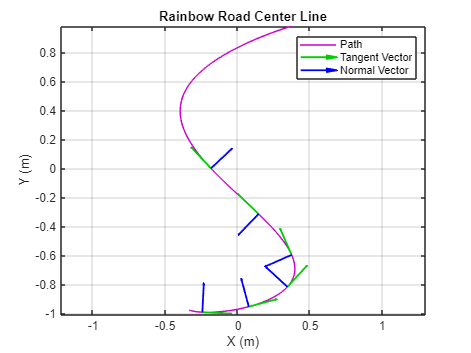

figure;
plot(rainbow_road_center_line_pos_data_x, rainbow_road_center_line_pos_data_y, Color=[0.8, 0, 0.8]); hold on
    for data_val = 5:10:60
        quiver( ...
            rainbow_road_center_line_pos_data_x(data_val), ...
            rainbow_road_center_line_pos_data_y(data_val), ...
            double(rainbow_road_center_line_tangent_vec_x(full_u_range(data_val))), ...
            double(rainbow_road_center_line_tangent_vec_y(full_u_range(data_val))), ...
            0.20, ...
            LineWidth=1.5, ...
            Color=[0, 0.8, 0] ...
        )
        quiver( ...
            rainbow_road_center_line_pos_data_x(data_val), ...
            rainbow_road_center_line_pos_data_y(data_val), ...
            double(rainbow_road_center_line_norm_vec_x(full_u_range(data_val))), ...
            double(rainbow_road_center_line_norm_vec_y(full_u_range(data_val))), ...
            0.20, ...
            LineWidth=1.5, ...
            Color=[0, 0, 1] ...
        )
    end
    legend("Path", "Tangent Vector", "Normal Vector")
    title("Rainbow Road Center Line")
    xlabel("X (m)"); ylabel("Y (m)")
    grid on
    axis equal;
hold off

Plot of the path of the neato, with tangent and normal vectors all across the path.

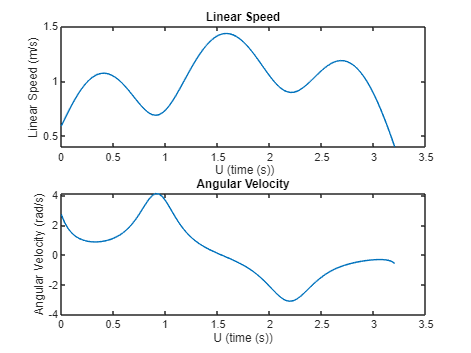

figure;
subplot(2, 1, 1)
plot(full_u_range, double(subs(rainbow_road_center_line_speed, u, full_u_range))); hold on
    title("Linear Speed")
    xlabel(" U (time (s))"); ylabel("Linear Speed (m/s)")
hold off

subplot(2, 1, 2)
plot(full_u_range, double(subs(rainbow_road_angular_velocity, u, full_u_range))); hold on
    title("Angular Velocity")
    xlabel("U (time (s))"); ylabel("Angular Velocity (rad/s)")
hold off

A better view of the experimental angular velocity and linear speed of the Neato.

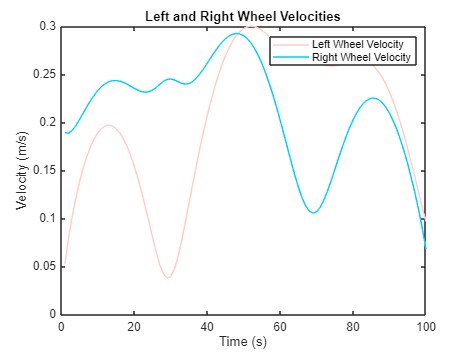

rainbow_road_vel_left_data = double(subs(rainbow_road_vel_left, u, full_u_range));
rainbow_road_vel_right_data = double(subs(rainbow_road_vel_right, u, full_u_range));
scaling_factor = max(rainbow_road_vel_left_data) / 0.3;

figure;
plot(rainbow_road_vel_left_data ./ scaling_factor, Color=[1, 0.8, 0.8]); hold on
    plot(rainbow_road_vel_right_data ./ scaling_factor, Color=[0, 0.8, 1]);
    title("Left and Right Wheel Velocities")
    legend("Left Wheel Velocity", "Right Wheel Velocity")
    xlabel("Time (s)"); ylabel("Velocity (m/s)")
hold off

Left and Right Wheel Experimental Velocities, in a better view.

EXERCISE 6.4

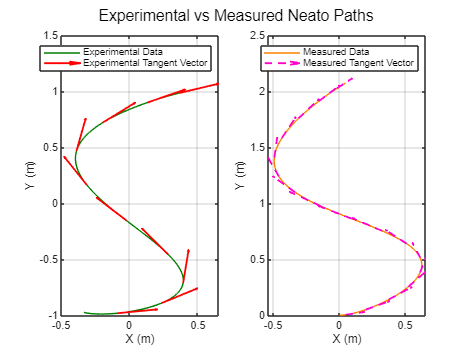

load("neato_data.mat")

t_list = recorded_data(1:172, 1);
left_encoder_data = recorded_data(1:172, 2);
right_encoder_data = recorded_data(1:172, 3);
left_vel_data = recorded_data(1:172, 4);
right_vel_data = recorded_data(1:172, 5);

left_vel_approx = diff(left_encoder_data) ./ diff(t_list);
right_vel_approx = diff(right_encoder_data) ./ diff(t_list);

rotation_rate = (right_vel_data - left_vel_data) / wheel_dist;
orientation = [0; cumsum(rotation_rate(1:end-1) .* diff(t_list))];

neato_fwd_vel = (left_vel_data + right_vel_data) / 2;

vel_x = cos(orientation) .* neato_fwd_vel;
vel_y = sin(orientation) .* neato_fwd_vel;

x_pos =  [0; cumsum(vel_x(1:end-1) .* diff(t_list))];
y_pos = [0; cumsum(vel_y(1:end-1) .* diff(t_list))];

x_vel = diff(x_pos) ./ diff(t_list);
y_vel = diff(y_pos) ./ diff(t_list);

speed = norm([x_vel, y_vel]);

tangent_x = x_vel ./ speed;
tangent_y = y_vel ./ speed;

q_x = diff(tangent_x);
q_y = diff(tangent_x);

norm_x = q_x ./ norm(q_x);
norm_y = q_y ./ norm(q_y);

angular_velocity = tangent_x(1:end-1) .* q_y - tangent_y(1:end-1) .* q_x;

figure;
sgtitle("Experimental vs Measured Neato Paths")
subplot(1, 2, 1)
exp_plot = ...
plot(double(subs(rr_x, t, t_vals)), double(subs(rr_y, t, t_vals)), Color=[0, 0.5, 0]); hold on
    exp_vals = [];  
    i = 1;
    for val = t_vals
        if (mod(i, 10) == 0)
            exp_vals(i) = quiver( ...
                double(subs(rr_x, t, val)), ...   
                double(subs(rr_y, t, val)), ...
                double(subs(rr_tang_x, t, val)), ...
                double(subs(rr_tang_y, t, val)), ...
                0.30, ...
                Color=[1, 0, 0], ...
                LineWidth=1.5 ...
            );
        end
        i = i + 1;
    end
    
    legend("Experimental Data", "Experimental Tangent Vector", Location="North")
    xlabel("X (m)"); ylabel("Y (m)")
    grid on;
hold off

subplot(1, 2, 2)
measure_plot = ...
plot(x_pos, y_pos, Color=[1, 0.5, 0]); hold on
    measure_vals = [];
    i = 1;
    for val = 5:10:length(tangent_x)
        measure_vals(i) = quiver( ...
            x_pos(val), ...
            y_pos(val), ...
            tangent_x(val), ...
            tangent_y(val), ...
            2, ...
            Color=[1, 0, 0.8], ...
            LineStyle="--", ...
            LineWidth=1.5 ...
        );
        i = i + 1;
    end

    legend([measure_plot, measure_vals(1)], "Measured Data", "Measured Tangent Vector", Location="North")
    xlabel("X (m)"); ylabel("Y (m)")
    grid on;
hold off

Both of the Neato's paths, experimental and measured. Measured isn't perfect, but it follows the path relatively closely. The tangent vectors in the measured data line up a little more closely than the ones in the experimental data.

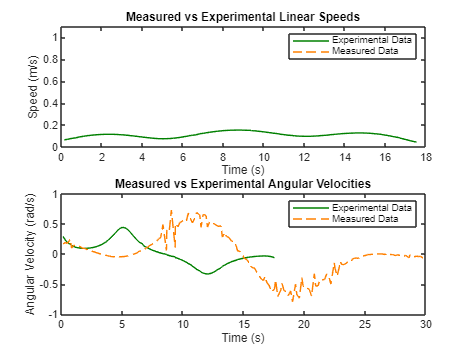

figure;
subplot(2, 1, 1)
plot(t_list(1:100), double(subs(rr_speed, t, t_vals)), Color=[0, 0.5, 0]); hold on
    plot(speed, Color=[1, 0.5, 0], LineStyle="--");
    legend("Experimental Data", "Measured Data")
    xlabel("Time (s)"); ylabel("Speed (m/s)")
    title("Measured vs Experimental Linear Speeds")
hold off

subplot(2, 1, 2)
plot(t_list(1:100), double(subs(rr_ang_vel, t, t_vals)), Color=[0, 0.5, 0]); hold on
    plot(t_list(1:170), angular_velocity * 10^3, Color=[1, 0.5, 0], LineStyle="--");
    legend("Experimental Data", "Measured Data", Location="Northeast")
    ylabel("Angular Velocity (rad/s)"); xlabel("Time (s)")
    title("Measured vs Experimental Angular Velocities")
hold off

Subplots of the Neato's linear speeds, and angular velocities. The linear speeds are the exact same, but the angular velocities are extremely different, but following the same general curve.

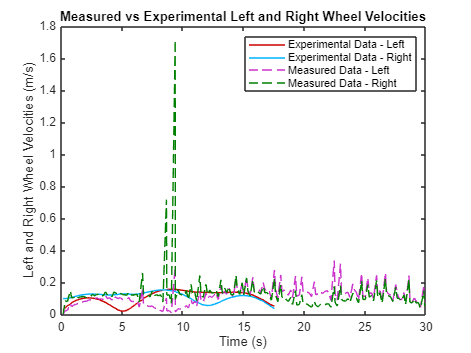

figure;
plot(t_list(1:100), double(subs(rr_vel_left, t, t_vals)), Color=[0.8, 0, 0]); hold on
    plot(t_list(1:100), double(subs(rr_vel_right, t, t_vals)), Color=[0, 0.7, 1]);
    plot(t_list(1:171), left_vel_approx, Color=[0.8, 0.2, 0.8], LineStyle="--");
    plot(t_list(1:171), right_vel_approx, Color=[0, 0.5, 0], LineStyle="--");
    legend("Experimental Data - Left", "Experimental Data - Right", "Measured Data - Left", "Measured Data - Right")
    xlabel("Time (s)"); ylabel("Left and Right Wheel Velocities (m/s)")
    title("Measured vs Experimental Left and Right Wheel Velocities")
hold off

All of the Neato's experimental and measured left and right wheel velocities. The right wheel in the measured data peaks, but otherwise the measured and experimental data stay within the same range (0-0.3).

EXERCISE 6.5

[Rainbow Road Video](https://youtube.com/shorts/hMUFsXxHvaw?si=9iIeN9GWDy260W5W)